[status,sheets] = xlsfinfo('Nguyen D-Proj2020.xls')%shows that 3 sheets exist

status = 'Microsoft Excel Spreadsheet'

sheets = 1×3 cell array
    {'Sheet1'}    {'Sheet2'}    {'Sheet3'}


% the command to read the data
[A,names,raw] =xlsread('Nguyen D-Proj2020.xls',1);% reads the first sheet only
LN=length(names) % number of columns with names

LN = 0

A % data only

A =     2.4314
    0.3121
    1.0142
    3.0086
    1.0297
    1.2884
    1.3529
    1.0989
    3.5893
    0.5788


names % headers


names =

  0×0 empty cell array



raw % headers and data

raw = 130×1 cell array
    {[2.4314]}
    {[0.3121]}
    {[1.0142]}
    {[3.0086]}
    {[1.0297]}
    {[1.2884]}
    {[1.3529]}
    {[1.0989]}
    {[3.5893]}
    {[0.5788]}
    {[2.4068]}
    {[2.9139]}
    {[1.4217]}
    {[0.8587]}
    {[1.5361]}
    {[2.4029]}


data = A(:,1)% get the first colum data

data =     2.4314
    0.3121
    1.0142
    3.0086
    1.0297
    1.2884
    1.3529
    1.0989
    3.5893
    0.5788


% x and y are of different lengths. Because of this, y contains NaN
 % suppress the NaN
% plot the histograms
Abs = data(1:70,:)

Abs =     2.4314
    0.3121
    1.0142
    3.0086
    1.0297
    1.2884
    1.3529
    1.0989
    3.5893
    0.5788


Prs = data(71:130)

Prs =     5.7331
    3.8609
    1.2206
    5.3431
    3.3433
    3.4067
    1.2816
    1.5774
    3.5515
    3.2714



N0=length(Abs);
N1=length(Prs);

dat=[Abs;Prs];% data in a single column
resp=[zeros(N0,1);ones(N1,1)]; % labels
[pf,pd,T,AUC,OPTOCPT]=perfcurve(resp,dat,1);

figure,plot(pf,pd,'k', 'LineWidth', 1.3)
hold on

% pf = 0.283 for intersection review HW3 part 2 which is element 57 in array pf
%plot(pf(57),pd(57),'ks')
hold on
%Handle gamma fit here
pd_abs = fitdist(Abs, "Gamma")

pd_abs =   GammaDistribution

  Gamma distribution
    a =  2.76011   [2.01764, 3.77581]
    b = 0.616095   [0.436939, 0.868711]


pd_pre = fitdist(Prs, "Gamma")

pd_pre =   GammaDistribution

  Gamma distribution
    a = 4.05053   [2.8712, 5.71427]
    b = 1.02097   [0.707786, 1.47273]


a1 = 2.76011; b1 = 0.616095;
a2 = 4.05053; b2 = 1.02097;
thr = 0:0.2:150;
PF = 1 -cdf('gamma',thr,a1, b1);
PD = 1 - cdf('Gamma', thr, a2, b2);
plot(PF, PD, 'r', 'LineWidth',1.3)
AUC1 = trapz(sort(PF), sort(PD));
AUC2 = polyarea(PF, PD) + 0.5;

%find min distance point to the top
distop = sqrt( (0-pf).^2 + (1-pd).^2)

distop =     1.0000
    0.9833
    0.9667
    0.9500
    0.9333
    0.9167
    0.9000
    0.8833
    0.8667
    0.8500


opt = find(distop == min(distop))

opt = 55

plot(pf(opt),pd(opt),'o', 'MarkerFaceColor', 'g')
plot([0,pf(opt)], [1,pd(opt)], 'b', 'LineWidth',1.3)
%calculate distance from intersection to the top
distsec = sqrt( (0-pf(opt))^2 + (1-pd(opt))^2 )

distsec = 0.3025

txt0 = {"d_m_i_n =", num2str(distsec)};
text(0.1, 0.9, txt0)
txt = {'d_m_i_n (intersection) = 0.332', 'd_m_i_n (midpoint) = 0.311'};
text(0.6,0.4,txt)

line =0:0.01:1

line =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


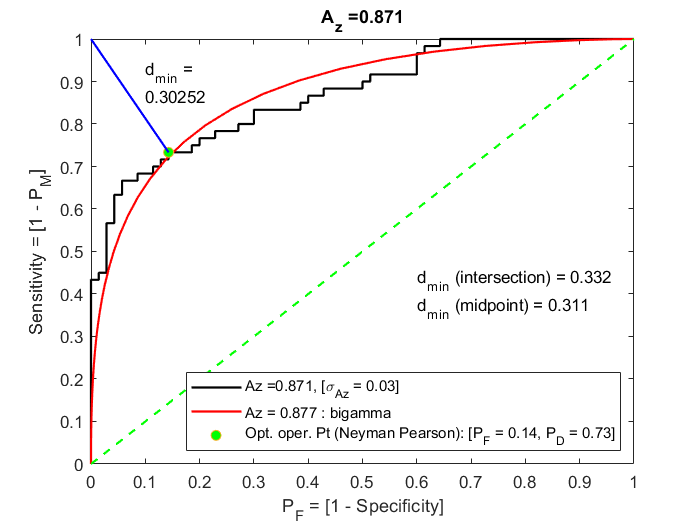

plot(line,line,'--g', 'LineWidth', 1.3)
title("A_z =0.871")
ylabel('Sensitivity = [1 - P_M]'),xlabel('P_F = [1 - Specificity]')
legend('Az =0.871, [\sigma_A_z = 0.03]','Az = 0.877 : bigamma','Opt. oper. Pt (Neyman Pearson): [P_F = 0.14, P_D = 0.73]','Location','southeast')
hold off




% create the threshold based on CDF
TT=sort(dat,'descend');
TT=[TT;0];

% disp([T,TT])
% now get the bootstrap samples
nB=100;% number of boot samples
btarea=bootstrp(nB,@calculateROCarea,resp,dat);
perindex = abs( mean(Abs) - mean(Prs) ) / sqrt( std(Abs) ^ 2 + std(Prs) ^ 2)

perindex = 1.0871

std_dev = std(btarea)

std_dev = 0.0299

figure;hold on
xx0=0:0.01:1.2*max(Abs)

xx0 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


xx1=0:0.01:1.2*max(Prs)

xx1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


fx0=ksdensity(Abs,xx0,'function', 'pdf')

fx0 =     0.1043    0.1069    0.1095    0.1121    0.1147    0.1174    0.1201    0.1229    0.1256    0.1284    0.1312    0.1340    0.1369    0.1398    0.1427    0.1456    0.1485    0.1515    0.1545    0.1574    0.1605    0.1635    0.1665    0.1695    0.1726    0.1757    0.1787    0.1818    0.1849    0.1880    0.1911    0.1942    0.1973    0.2005    0.2036    0.2067    0.2098    0.2129    0.2160    0.2191    0.2222    0.2253    0.2284    0.2315    0.2345    0.2376    0.2406    0.2437    0.2467    0.2497


fx1=ksdensity(Prs,xx1,'function','pdf')

fx1 =     0.0239    0.0243    0.0247    0.0251    0.0255    0.0259    0.0263    0.0267    0.0272    0.0276    0.0280    0.0285    0.0289    0.0294    0.0298    0.0303    0.0307    0.0312    0.0316    0.0321    0.0326    0.0331    0.0336    0.0340    0.0345    0.0350    0.0355    0.0360    0.0365    0.0371    0.0376    0.0381    0.0386    0.0391    0.0397    0.0402    0.0407    0.0413    0.0418    0.0424    0.0429    0.0435    0.0440    0.0446    0.0452    0.0457    0.0463    0.0469    0.0475    0.0481


fit0 = plot(xx0, fx0, '-r', 'linewidth',1.5);
fit1 = plot(xx1, fx1, '-k', 'linewidth',1.5);
fit1.LineStyle = '--';

%% replace optimum threshold here is 2.79

lx0 = linspace(0,fx0(280))

lx0 =          0    0.0020    0.0041    0.0061    0.0081    0.0101    0.0122    0.0142    0.0162    0.0183    0.0203    0.0223    0.0244    0.0264    0.0284    0.0304    0.0325    0.0345    0.0365    0.0386    0.0406    0.0426    0.0447    0.0467    0.0487    0.0507    0.0528    0.0548    0.0568    0.0589    0.0609    0.0629    0.0650    0.0670    0.0690    0.0710    0.0731    0.0751    0.0771    0.0792    0.0812    0.0832    0.0853    0.0873    0.0893    0.0913    0.0934    0.0954    0.0974    0.0995


lx1 = 2.79*ones(1,100)

lx1 =     2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900    2.7900


xx0a = xx0(280:length(xx0))

xx0a =     2.7900    2.8000    2.8100    2.8200    2.8300    2.8400    2.8500    2.8600    2.8700    2.8800    2.8900    2.9000    2.9100    2.9200    2.9300    2.9400    2.9500    2.9600    2.9700    2.9800    2.9900    3.0000    3.0100    3.0200    3.0300    3.0400    3.0500    3.0600    3.0700    3.0800    3.0900    3.1000    3.1100    3.1200    3.1300    3.1400    3.1500    3.1600    3.1700    3.1800    3.1900    3.2000    3.2100    3.2200    3.2300    3.2400    3.2500    3.2600    3.2700    3.2800


fx0a = fx0(280:length(fx0))

fx0a =     0.2010    0.1995    0.1980    0.1965    0.1950    0.1936    0.1921    0.1906    0.1890    0.1875    0.1860    0.1845    0.1829    0.1814    0.1799    0.1783    0.1767    0.1752    0.1736    0.1720    0.1705    0.1689    0.1673    0.1657    0.1641    0.1625    0.1609    0.1593    0.1577    0.1561    0.1545    0.1529    0.1513    0.1496    0.1480    0.1464    0.1448    0.1432    0.1416    0.1400    0.1383    0.1367    0.1351    0.1335    0.1319    0.1303    0.1287    0.1271    0.1256    0.1240


h1 = area(xx0a,fx0a)

h1 =   Area with properties:

    FaceColor: [0.9290 0.6940 0.1250]
    EdgeColor: [0 0 0]
    LineStyle: '-'
    LineWidth: 0.5000
    BaseValue: 0
        XData: [1×244 double]
        YData: [1×244 double]

  Show all properties




xx1b = xx1(1:280)

xx1b =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


fx1b = fx1(1:280)

fx1b =     0.0239    0.0243    0.0247    0.0251    0.0255    0.0259    0.0263    0.0267    0.0272    0.0276    0.0280    0.0285    0.0289    0.0294    0.0298    0.0303    0.0307    0.0312    0.0316    0.0321    0.0326    0.0331    0.0336    0.0340    0.0345    0.0350    0.0355    0.0360    0.0365    0.0371    0.0376    0.0381    0.0386    0.0391    0.0397    0.0402    0.0407    0.0413    0.0418    0.0424    0.0429    0.0435    0.0440    0.0446    0.0452    0.0457    0.0463    0.0469    0.0475    0.0481


h2 = area(xx1b,fx1b)

h2 =   Area with properties:

    FaceColor: [0.4940 0.1840 0.5560]
    EdgeColor: [0 0 0]
    LineStyle: '-'
    LineWidth: 0.5000
    BaseValue: 0
        XData: [1×280 double]
        YData: [1×280 double]

  Show all properties



h1.FaceColor = [0 1 0];
h2.FaceColor = [1 1 0];
%plot(lx1,lx0,'k');
ylabel('estimated pdf'); xlabel('values (v)');
legend('f_V(v|H_0)','f_V(v|H_1)');
title('density fit');
p1_arrow = [0.31 0.31] %x range of arrow

p1_arrow =     0.3100    0.3100


p2_arrow = [0.11 0.9] % y range of arrow

p2_arrow =     0.1100    0.9000


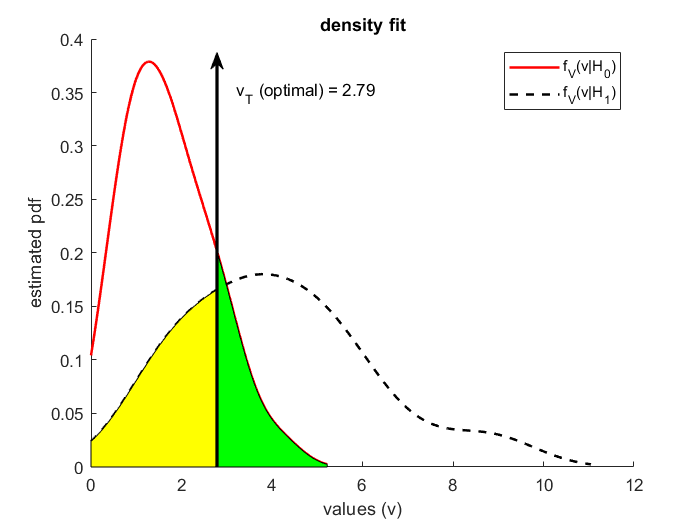

annotation('textarrow', p1_arrow, p2_arrow, 'LineWidth', 2)
txt_optimal = {'v_T (optimal) = 2.79'};
text(3.2, 0.35, txt_optimal)

function area=calculateROCarea(resp,dat)
[pf,pd,T,AUC]=perfcurve(resp,dat,1);
area=AUC;
end